L = [3 25 4 24];
D = 25;
th1 = pi/2;
x0 = [0 3/2*pi];

draw_mechanism_old(L,th1,x0)
axis([-10 30 -20 20])
hold on

x = fsolve(@(x) error(L,th1,x),x0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


draw_mechanism_old(L,th1,x)

th1 = -pi/2;
x = fsolve(@(x) error(L,th1,x),x0);


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


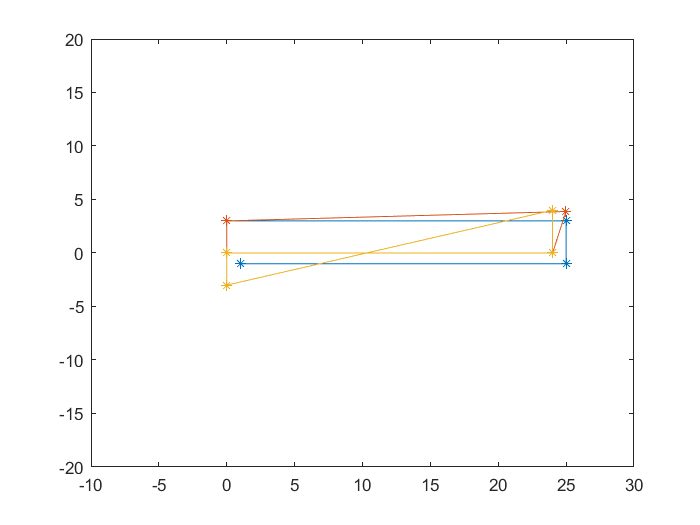

draw_mechanism_old(L,th1,x)

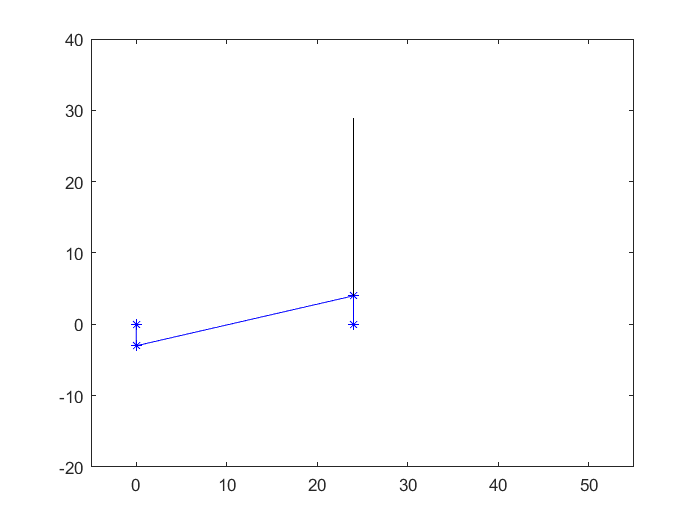


Equation solved at initial point.

fsolve completed because the vector of function values at the initial point
is near zero as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the 


figure
for th1 = linspace(-pi/2,4*pi-pi/2)
    x = fsolve(@(x) error(L,th1,x),x);
    draw_mechanism(L,D,th1,x);
    axis([-5 55 -20 40])
    pause(0.1)
end

function p4 = error(L,th1,x)

p1 =      L(1)*[cos(th1);  sin(th1) ];
p2 = p1 + L(2)*[cos(x(1)); sin(x(1))];
p3 = p2 + L(3)*[cos(x(2)); sin(x(2))];
p4 = p3 + L(4)*[-1;        0        ];

end

function draw_mechanism_old(L,th1,x)

p0 = [0;0];
p1 = p0 + L(1)*[cos(th1);  sin(th1) ];
p2 = p1 + L(2)*[cos(x(1)); sin(x(1))];
p3 = p2 + L(3)*[cos(x(2)); sin(x(2))];
p4 = p3 + L(4)*[-1;        0        ];

P = [p0 p1 p2 p3 p4];
plot(P(1,:),P(2,:),'-*')

end

function draw_mechanism(L,D,th1,x)

p0 = [0;0];
p1 = p0 + L(1)*[cos(th1);  sin(th1) ];
p2 = p1 + L(2)*[cos(x(1)); sin(x(1))];
p3 = p2 + L(3)*[cos(x(2)); sin(x(2))];

P = [p0 p1 p2 p3];
plot(P(1,:),P(2,:),'-*b')
hold on

r2 = p2 - D(1)*[cos(x(2)); sin(x(2))];
R = [p2 r2];
plot(R(1,:),R(2,:),'k')
hold off

end